# Example: Basic Solver for Acoustics in 2D

This live-script features the following:

- 2D example

- construct acoustic sources via functions

- setup to run basic acoustic solver

- different visualizations

- plot for medium parameters

- animate for solutions

- animateMedBack for solutions

- plotTimeSeries for solutions

Acoustic equations: 


$$\frac{\partial p}{\partial t} + \kappa \left( \frac{\partial v_x}{\partial x}  + \frac{\partial v_y}{\partial y}\right)= f_p$$



$$\frac{\partial v_x}{\partial t} + \beta \frac{\partial p}{\partial x} = f_{v_x}$$



$$\frac{\partial v_y}{\partial t} + \beta \frac{\partial p}{\partial y} = f_{v_y}$$


assuming zero-pressure at boundaries, and initial conditions provided by user.

First, the computational spatial grid is defined and used to initialize the grid space for the pressure fields.

clear

domain_x = [0,1];
domain_y = [0,1.5];
domain_t = [0,0.7];

% Computational and grid space
Nx = 161;
Ny = 201;
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
gsp_P = GridSpace2D(grid_x_primal,grid_y_primal);
h = gsp_P.h; %spatial grid sizes, h = [dx,dy]

Second, medium parameters are specified as a continuous function

- $\kappa(x,y)$ is the bulk modulus

- $\beta(x,y)$ is the buoyancy (reciprocal of density)

The function sampleMedium samples the acoustic medium parameters over a specified grid space. A staggered FDM is assumed, and thus the buoyancy will be sampled over the appropriate staggered/dual grid space.

The sample function also compute the wave speed, $c = \sqrt{\kappa \beta}$, and the maximum wave speed $c_{\rm max}$ required to compute an appropriate time step-size $\Delta_t$. 

The medium parameters are sampled for plotting purposes.

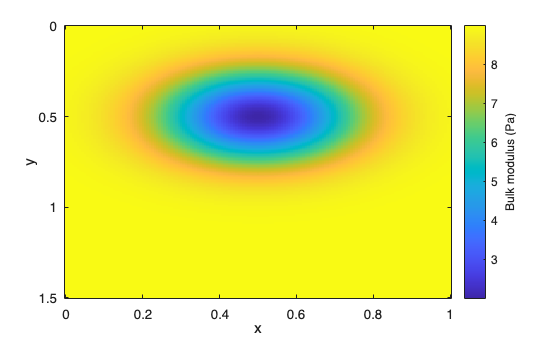

% Acoustic medium parameters 
% medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
medium = AcousticMedium2D.gaussian( ...
    BetaInside=1/2, ...
    BetaOutside=1, ...
    KappaInside=2, ...
    KappaOutside=9, ...
    Center=[0.5,0.5], ...
    Width=0.25);

[kappa,betaX,betaY,wavespeed,cMax] = sampleMedium2D(gsp_P,medium); %sampled on grids

kappa.plot;

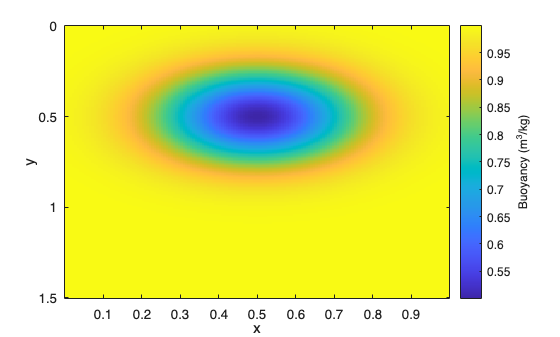

betaX.plot;

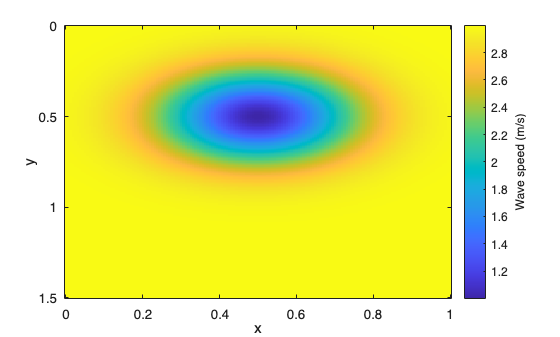

wavespeed.plot;

Unlike the spatial grid, we store the temporal grid as a simple array of time points.

For the 2-4 staggered FD scheme in 2D, we take $\Delta_t$ such that 

$\Delta_t \le \frac{6}{7} \left( c_{\rm max} \sqrt{ \frac{1}{\Delta_x^2} + \frac{1}{\Delta_y^2} } \right)^{-1}$.

When computing $\Delta_t$, it is important to ensure that the computational time interval is divisible by the step-size. Usually this requires a recomputation of $\Delta_t$ as done so here.

% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2))); %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

These next couple of steps can be done in no particular order.

Here we specify the out spatial grid and time points. In this example we sample the entire spatial and temporal domains, though in practice we may only be interested in a small collection of spatial points.

% Ouput spatial grid and time points
gsp_out = GridSpace2D( ...
    Grid1DUnifPrimal(domain_x,81), ...
    Grid1DUnifPrimal(domain_y,81));
t_pts_out = linspace(domain_t(1),domain_t(2),51);

Here we specify an acoustic source in the pressure equation only. In particular, it is assumed that the source is separable, that is, of the form 


$$f_p(x,y,t) = p(x,y)q(t)$$
 

for some specified $p(x,y)$ and $q(t)$. In this example we have


$$p(x,y) = \exp\left(  - \frac{(x-x_c)^2}{x_w^2} - \frac{(y-y_c)^2}{y_w^2} \right)$$



$$q(t) = \exp\left(-\frac{(t-t_c)^2}{t_w^2} \right)$$


% Smooth pressure source centered away from the boundary
xc = 0.25; xw = 0.045;
yc = 0.25; yw = 0.045;
tc = 0.08; tw = 0.018;
source = AcousticSource2D( ...
    @(x,y) exp(-((x-xc)/xw).^2-((y-yc)/yw).^2), ...
    @(t) exp(-((t-tc)/tw).^2));

Here we specify the initial conditions functions such that


$$p(x,y,0) = p_0(x,y)$$



$$v_x(x,y,0) = v_{x,0}(x,y)$$



$$v_y(x,y,0) = v_{y,0}(x,y)$$


% Initial data
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

Before running the solver, we must initialize it using the computational grid space and time points, output grid space and time points, and medium parameters.

% Initializing solver
solver = AcousticSolver2DStaggered( ...
    gsp_P,t_pts,...
    gsp_out,t_pts_out,...
    medium, ...
    SpatialOrder=4);

To run the solver, we make use of the `solve()` method, and input the initial conditions, along with the acoustic source.

The outputs/solutions are of type `GridFunctionTimeSeries`.

% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

Objects of type `GridFunctionTimeSeries` class method `obj.animate()` for visualizing solutions as grid functions vs x, animated over time.

The `obj.animate()` method is recommended when visualizing the time evolution of the full grid function.

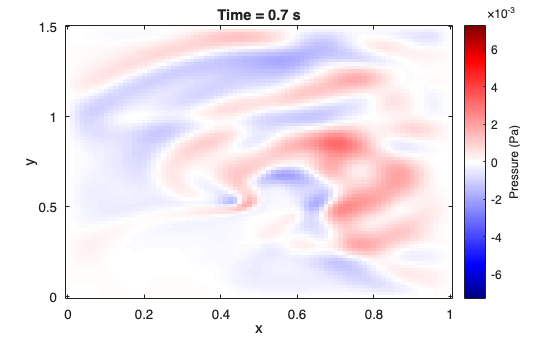

ax = axes(figure(Name="Pressure")); %This names the figure tab.
P.animate(FramePause=0.03,Parent=ax);

Here we make use of the `obj.snapshot()` method to visualize a snapshot of the pressure field at the final time, which returns an object of type `GridFunction`. The method `obj.plot()` for `GridFunction` is then used to visualize the pressure field.

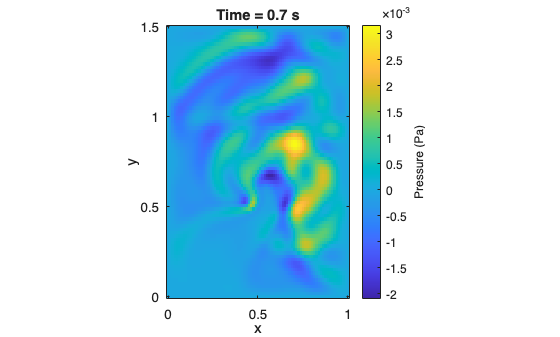

ax = axes(figure(Name="Final pressure"));
finalPressure = P.snapshot(P.Nt);
finalPressure.plot(Parent=ax);
axis image
title(P.formattedTime(P.Nt));
ax.YDir="normal"; %This ensures the y-axis has normal orientation

Another option for visualization is the method obj`.animateMedBack()`, which is similar to obj`.animate()` but it also plots the wave speed in the background. 

The obj`.animateMedBack()` method is recommended for visualizing the effects of acoustic media, in particular reflections due to medium discontinuities.

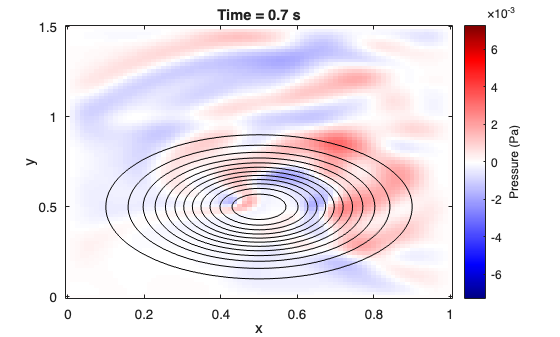

P.animateMedBack(medium);

Another option for visualization is the method obj`.plotTimeSeries()`, which plots the receiver index versus time. Each point in the output grid is interpreted as a receiver and indexed.

The obj`.plotTimeSeries()` method is recommended for visualizing data as a time series.

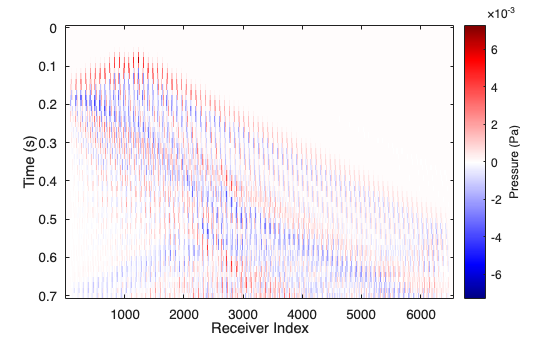

P.plotTimeSeries;